# 2. Interpreting Network - Convolution, ReLU, Max Pooling Layers

## Activations

image = imread("face.jpg")

image = 384×384×3 uint8 배열
image(:,:,1) =

   231   231   231   231   231   231   231   231   232   232   232   231   231   230   230   230   231   231   231   231   231   231   231   231   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   233   233   233   233   233   233   233   233   231   231   231   231   231   231   231   231   232   232   232   232   232   232   232   232   231   231   231   231   231   231   231   231   229   229   230   231   233   234   235   235   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   233   233   233   233   233   233   233   

sz = size(image)

sz =    384   384     3


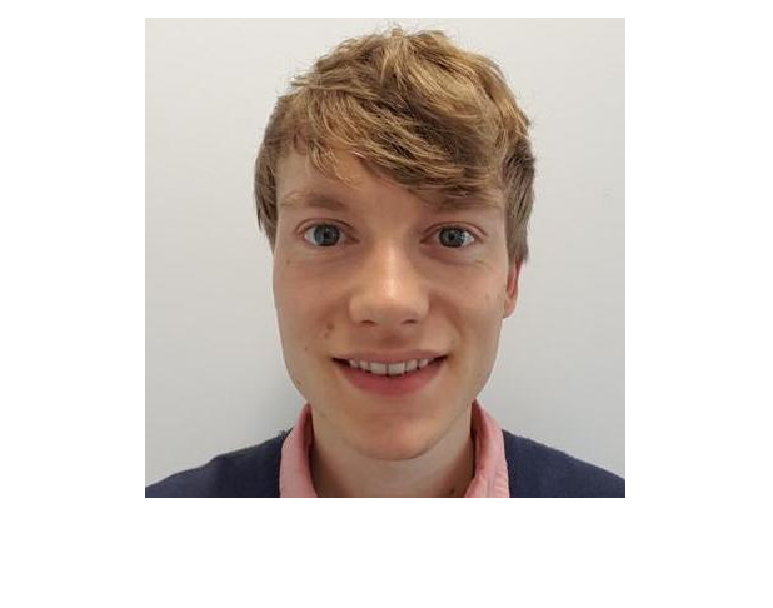

imshow(image)

net = imagePretrainedNetwork("squeezenet"); % Load SqueezeNet
layers = net.Layers % Save and view the layers of SqueezeNet

layers =   다음 계층을 포함한 68×1 Layer 배열:

     1   'data'                    영상 입력              227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'                   2차원 컨벌루션          64개 3×3×3 컨벌루션(스트라이드: [2  2], 채우기: [0  0  0  0])
     3   'relu_conv1'              ReLU                  ReLU
     4   'pool1'                   2차원 최댓값 풀링       3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     5   'fire2-squeeze1x1'        2차원 컨벌루션          16개 1×1×64 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     6   'fire2-relu_squeeze1x1'   ReLU                  ReLU
     7   'fire2-expand1x1'         2차원 컨벌루션          64개 1×1×16 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     8   'fire2-relu_expand1x1'    ReLU                  ReLU
     9   'fire2-expand3x3'         2차원 컨벌루션          64개 3×3×16 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    10   'fire2-relu_expand3x3'    ReLU                  ReLU
    11   'fire2-concat'            심도 

View the network architecture

analyzeNetwork(net)

### Show Activations of First Convolutional Layer

Activation: Information passed between the network layers.

You can extract the activations from a layer by using minibatchpredict function.

layers(2) % View the hyperparameters and learnable parameters of the first convolution layer

ans =   Convolution2DLayer - 속성 있음:

              Name: 'conv1'

   하이퍼파라미터
        FilterSize: [3 3]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [0 0 0 0]
      PaddingValue: 0

   학습 가능한 파라미터
           Weights: [3×3×3×64 single]
              Bias: [1×1×64 single]

  모든 속성 표시


actvn1 = minibatchpredict(net,image,Outputs="conv1") % Extract the activations from the first convolution layer

actvn1 = 191×191×64 single 배열
actvn1(:,:,1) =

    0.1633    0.1633    0.1633   -0.0847    1.0350    0.8815   -0.4155   -0.2686    0.1792    0.1792    0.1792   -0.0689    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811   -0.0670    0.1829    0.1829    0.1829    0.6791    0.1792    0.1792    0.1792   -0.0689    0.1811    0.1811    0.1811   -0.8004   -3.3900   -3.3900   -3.3900   -4.6336   -7.1019   -2.1452    5.8227    5.8607    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811   -0.0670    0.1829    0.1829    0.1829    1.1701    1.7642    1.4539    1.4539    1.2058    1.4558    1.4558    1.4558    4.2667    1.7914   -5.2019   -2.9748   -5.6661   -7.3560   18.6434   10.3184   

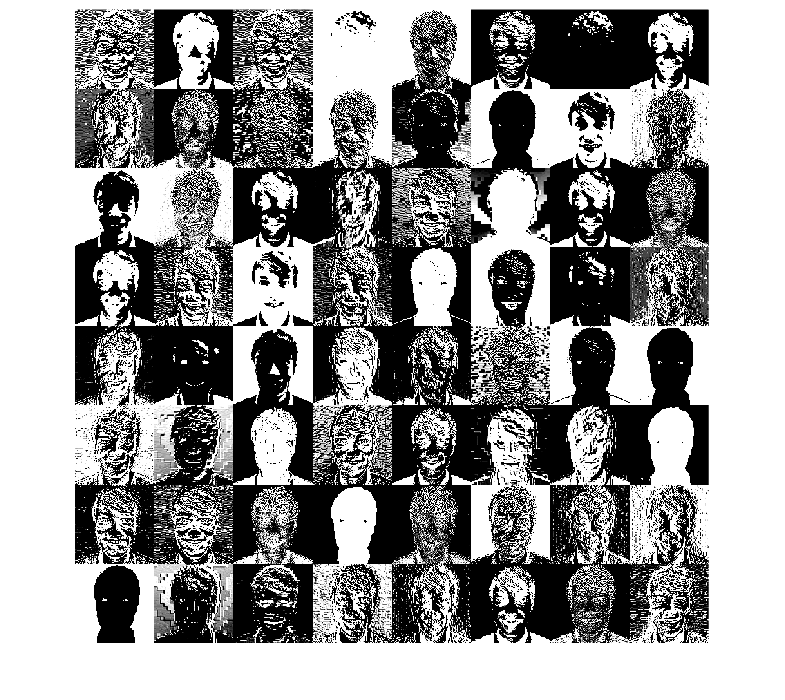


% Display the activation extracted from "conv1"
montage(actvn1)

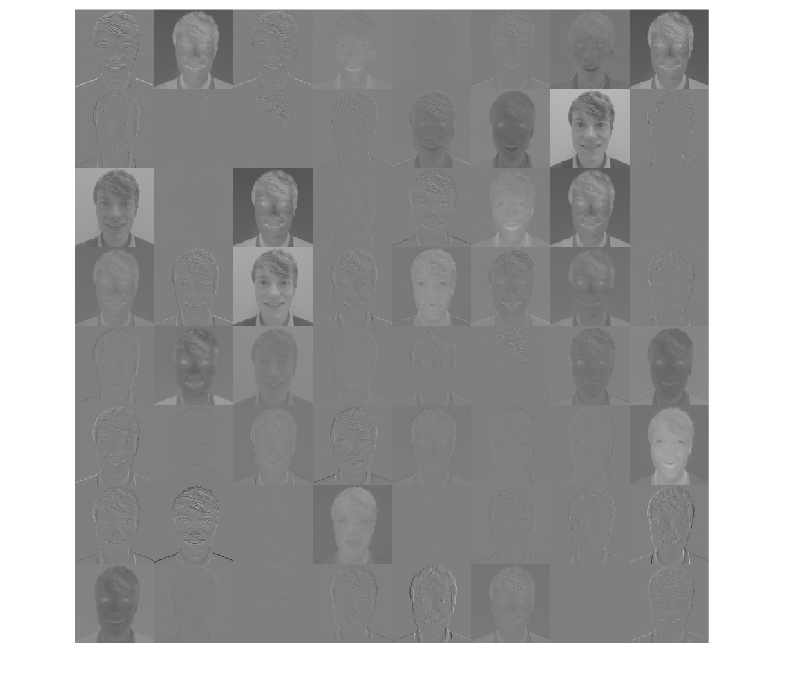

montage(mat2gray(actvn1))

size(actvn1)

ans =    191   191    64


### Investigate the activations in specific channels

Each tile in the grid of activations is the output of a channel in the `conv1` layer. White pixels represent strong positive activations and black pixels represent strong negative activations. A channel that is mostly gray does not activate as strongly on the input image. The position of a pixel in the activation of a channel corresponds to the same position in the original image. A white pixel at some location in a channel indicates that the channel is strongly activated at that position.

For channel 41,

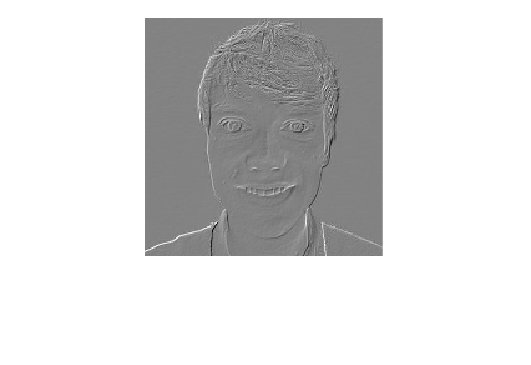

imshow(mat2gray(actvn1(:,:,41)))

size(actvn1(:,:,14))

ans =    191   191


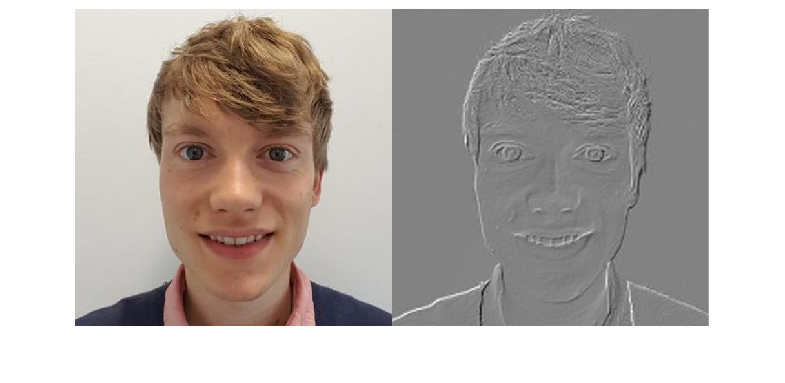


actvn1_ch41 = actvn1(:,:,41);
actvn1_ch41 = mat2gray(actvn1_ch41);
actvn1_ch41 = imresize(actvn1_ch41,sz(1:2)); % resize the activation in channel 41 in order to compare it with the original image

montage({image, actvn1_ch41}) % Display the original image and the activation in channel 41

For channel 22,

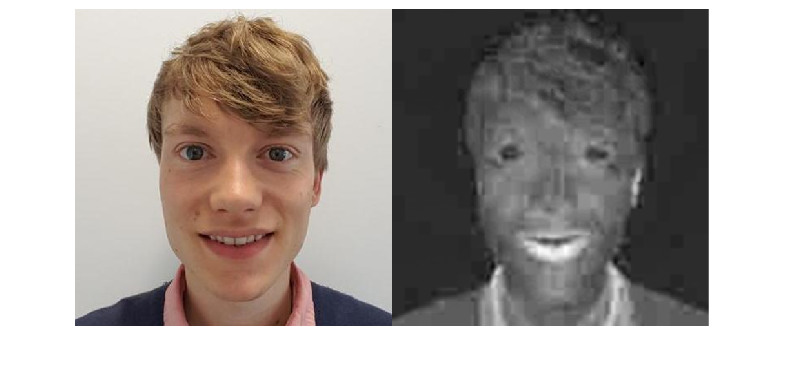

actvn1_ch22 = actvn1(:,:,22);
actvn1_ch22 = mat2gray(actvn1_ch22);
actvn1_ch22 = imresize(actvn1_ch22,sz(1:2)); % resize the activation in channel 22 in order to compare it with the original image

montage({image, actvn1_ch22}) % Display the original image and the activation in channel 22

## Deeper Layer Activations

Most convolutional neural networks learn to detect features like color and edges in their first convolutional layer. In deeper convolutional layers, the network learns to detect more complicated features. Later layers build up their features by combining features of earlier layers. Investigate the `fire6-squeeze1x1` layer in the same way as the `conv1` layer. Calculate, reshape, and show the activations in a grid.

actvn6 = minibatchpredict(net,image,...
    Outputs="fire6-squeeze1x1") % Extract the activations from "fire6-squeeze1x1" layer

actvn6 = 23×23×48 single 배열
actvn6(:,:,1) =

  129.4551   85.7528   59.4077   71.5334   82.3779   96.3230   93.6582    3.7620  -97.7361 -269.3255 -100.0955   23.0343 -133.3717 -149.0390    7.1643  138.0942   18.7709   70.3652  100.2226   74.9454   73.0920   75.9599   74.6420
   22.7668   20.2158    1.2559    7.6808    8.6969    2.3360  -27.4168 -152.8304 -108.7198 -114.7665  -43.7268   21.0280   17.0411  106.3885  218.3084   97.8596  -68.7969  -89.3009   36.5741   26.0875    6.6114   12.4167    5.2403
   19.9638   11.6099   -4.6195   -1.8408    2.8660  -35.1879  -80.8413  -69.5859   49.6175  115.2639   89.2822    3.1838   -4.8169   70.4283  108.6203   32.0218   55.0852   49.8635   18.9246   62.6168   12.7585    5.8803   -5.5998
   15.2440    6.4061   -7.4767   -2.8056   -9.6718  -78.4362  -51.8258  -28.4227  139.1640   57.6270   60.3458   60.8537   63.1078   97.1338   63.3904   -0.4448   62.1914  114.8438  -33.9879    1.5966   23.3734    7.4324  -11.3727
    6.7516    9.1377    1.7573 

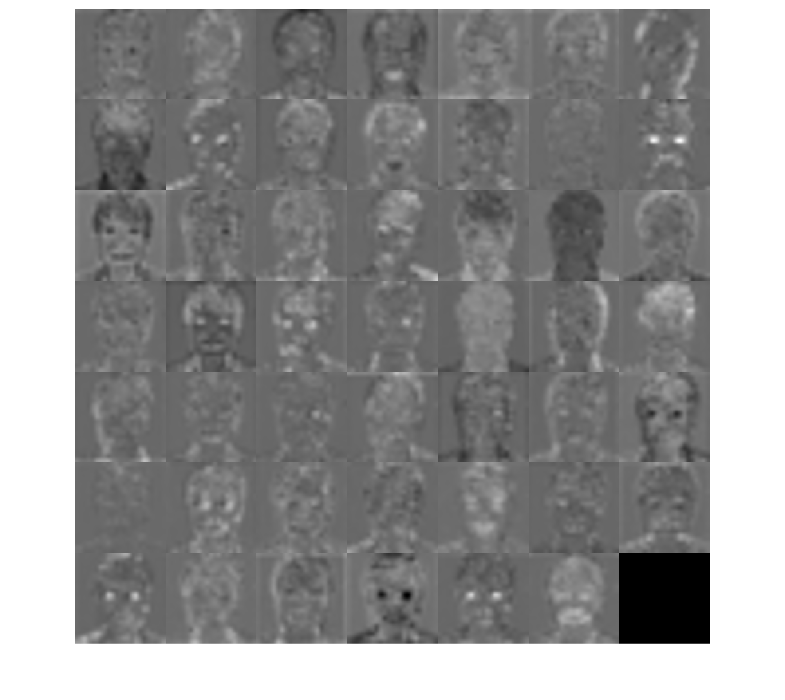


% Display the activation extracted from "fire6-squeeze1x1"
montage(mat2gray(actvn6))

For channel 47,

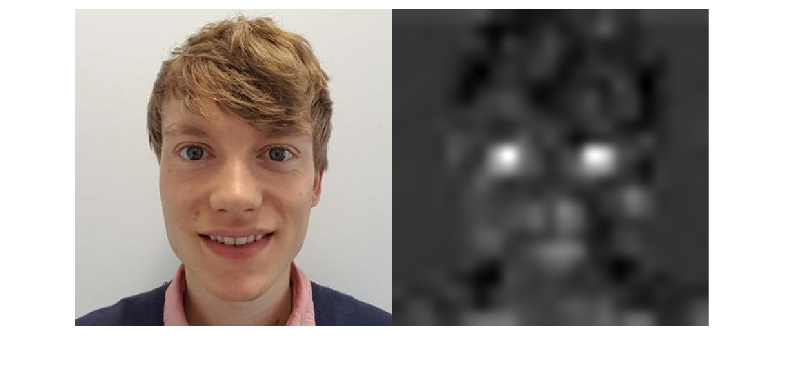

actvn6_ch47 = actvn6(:,:,47);
actvn6_ch47 = mat2gray(actvn6_ch47);
actvn6_ch47 = imresize(actvn6_ch47,sz(1:2)); % resize the activation in channel 47 in order to compare it with the original image

montage({image, actvn6_ch47}); % Display the original image and the activation in channel 47

## Following Activations in the Network Architecture

### Rectified Linear Unit (ReLU) Layer

ReLu layer apply a threshold to an input such that every value less than zero is set to zero. You will see that any negative activations from a convolution layer will be set to zero after passing through the ReLU layer.

actvn6_relu = minibatchpredict(net, image,...
    Outputs="fire6-relu_squeeze1x1") % Extract the activations from "fire6-relu_squeeze1x1" layer

actvn6_relu = 23×23×48 single 배열
actvn6_relu(:,:,1) =

  129.4551   85.7528   59.4077   71.5334   82.3779   96.3230   93.6582    3.7620         0         0         0   23.0343         0         0    7.1643  138.0942   18.7709   70.3652  100.2226   74.9454   73.0920   75.9599   74.6420
   22.7668   20.2158    1.2559    7.6808    8.6969    2.3360         0         0         0         0         0   21.0280   17.0411  106.3885  218.3084   97.8596         0         0   36.5741   26.0875    6.6114   12.4167    5.2403
   19.9638   11.6099         0         0    2.8660         0         0         0   49.6175  115.2639   89.2822    3.1838         0   70.4283  108.6203   32.0218   55.0852   49.8635   18.9246   62.6168   12.7585    5.8803         0
   15.2440    6.4061         0         0         0         0         0         0  139.1640   57.6270   60.3458   60.8537   63.1078   97.1338   63.3904         0   62.1914  114.8438         0    1.5966   23.3734    7.4324         0
    6.7516    9.1377 

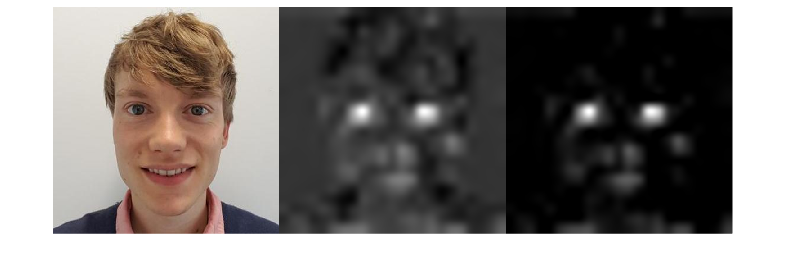

actvn6_relu_ch47 = actvn6_relu(:,:,47);
actvn6_relu_ch47 = mat2gray(actvn6_relu_ch47);
actvn6_relu_ch47 = imresize(actvn6_relu_ch47, sz(1:2));

montage({image, actvn6_ch47, actvn6_relu_ch47}, "Size",[1,3])

### Max Pooling Layer

Max pooling layers perform downsampling, which causes large activations to be more pronounced after passing through the pooling layer.

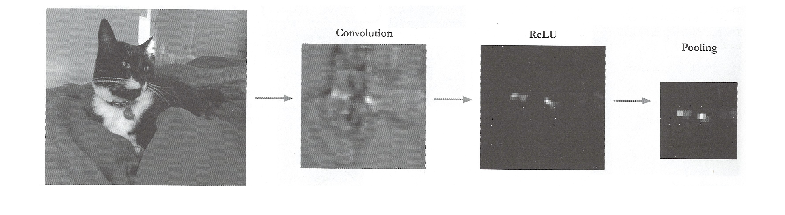

cnnLayerBehavior = imread("cnnLayerBehavior.jpg");
imshow(cnnLayerBehavior)